processingOptions = phoPipelineOptions.PhoPostFinalDataStructAnalysis.processingOptions;


curr_cellROI_index =21     

curr_cellROI_index = 21

curr_session_index = 2

curr_session_index = 2


curr_cellROI_compListIndicies = cellROIIndexMapper.getCompListIndicies(curr_cellROI_index);
curr_day_linear_comp_index = curr_cellROI_compListIndicies(curr_session_index); % The linear comp index, not the unique cellROI index

[currentAnm, currentSesh, currentComp] = fnBuildCurrIdentifier(activeCompList, curr_day_linear_comp_index); % TODO: potentially refactor into CellROIIndexMapper?
original.rawDFF = finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).imagingDataDFF;
fissa.rawDFF = finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).fissa_df_raw;  % 520x150 double. %assumes you have this field
% fissa.neuropilCorrectedDFF = squeeze(finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).fissa_df_result(1,:,:));  % 520x150 double. %assumes you have this field
% fissa.imgDataNeuropil = squeeze(sum(finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).fissa_df_result(2:end,:,:),1)); % 520x150 double
%       

fissa.neuropilCorrectedDFF = finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).fissa_raw.measured_cell_signal;  % 520x150 double. %assumes you have this field


[numTrials, outputs.numFramesPerTrial] = size(original.rawDFF);
% Smooth the curve
if processingOptions.smoothValue>0
    for i = 1:numTrials
        original.rawDFF(i,:) = smooth(original.rawDFF(i,:), processingOptions.smoothValue);
        if processingOptions.compute_neuropil_corrected_versions
            fissa.neuropilCorrectedDFF(i,:) = smooth(fissa.neuropilCorrectedDFF(i,:), processingOptions.smoothValue);
        end
    end
end

[~, outputs.numFramesPerTrial] = size(original.rawDFF);

active_fissa_var = fissa.neuropilCorrectedDFF;

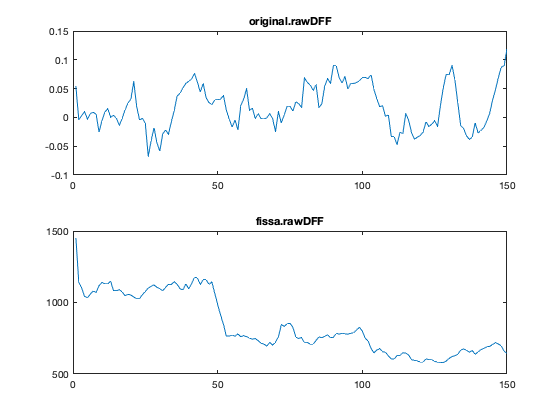

trial_index = 18;


figure;
clf;
subplot(2,1,1)
plot(original.rawDFF(trial_index,:));
title('original.rawDFF')
subplot(2,1,2)
plot(active_fissa_var(trial_index,:));
title('fissa.rawDFF')

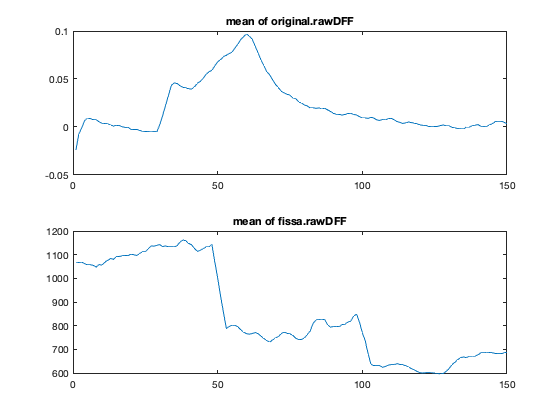

mean_dim = 1;
figure;
clf;
subplot(2,1,1)
plot(mean(original.rawDFF, mean_dim));
title('mean of original.rawDFF')
subplot(2,1,2)
plot(mean(active_fissa_var, mean_dim));
title('mean of fissa.rawDFF')